# Deconvolution Benchmark 2D: Matlab (DL2)

javaaddpath([matlabroot filesep 'java' filesep 'DeconvolutionLab_2.jar']);

addpath('/Users/yi/npy-matlab-master/npy-matlab'); % para poder cargar ficheros .npy


% Definir la carpeta donde se encuentran las imágenes que se van a emplear
folder = 'ImagenesEmpleadas2D';

## Test Image 2D

% Cargar la imagen y la PSF
img_test = single(readNPY(fullfile(folder, 'imagen_borrosa.npy')));
psf_test = single(readNPY(fullfile(folder, 'test_psf.npy')));

result_test = DL2.RL(img_test, psf_test, 30, '-out')

Log   	 355,67 us 	  179,1Mb  	 DeconvolutionLab2 2.1.2 (27.06.2018) on Matlab
Log   	 1169,50 us 	  253,4Mb  	 AcademicFFT Added
Log   	 7,18 ms 	  253,4Mb  	 JTransforms not found
Log   	 22,75 ms 	  256,2Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024b.app/java/FFTW/
Log   	 23,29 ms 	  256,8Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024b.app/java/
Log   	 23,59 ms 	  257,9Mb  	 FFTW Widsom not found in : /Users/yi/FFTW/
Log   	 23,69 ms 	  257,9Mb  	 FFTW Widsom not found in : /Users/yi/
Log   	 23,76 ms 	  258,5Mb  	 FFTW not found


result_test =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

Visualización y guardado del resultado:

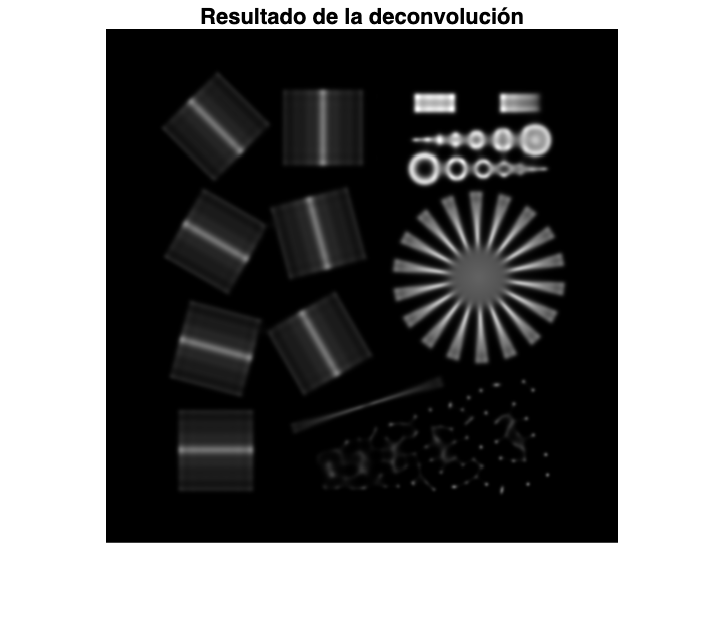

figure;
imshow(result_test, []);  % El [] ajusta automáticamente el rango de intensidad
colormap gray;            % Escala de grises
title('Resultado de la deconvolución');

imwrite(mat2gray(result_test), '2D_MATLAB_imagetest_DL2.png');  % mat2gray normaliza a [0,1]


### @ BENCHMARK

% ------------------------------
% Configuración
% ------------------------------
numIter = 10;                           % Número de ejecuciones
csvFile = 'RL_times_test.csv';               % Nombre del CSV de salida

% Eliminar archivo previo si existe
if exist(csvFile, 'file')
    delete(csvFile);
end

% ------------------------------
% Bucle de ejecución
% ------------------------------
T_test = zeros(numIter,1);  % Vector para guardar tiempos

for i = 1:numIter
    tic
    result_test = DL2.RL(img_test, psf_test, 30, '-out');  % Ejecutar deconvolución
    T_test(i) = toc;  % Guardar tiempo total
    
    % Guardar inmediatamente en CSV
    writematrix(T_test(i), csvFile, 'WriteMode', 'append');
    
    fprintf('Iteración %d: %.3f s\n', i, T_test(i));
end

Iteración 1: 2.850 s
Iteración 2: 2.583 s
Iteración 3: 2.582 s
Iteración 4: 2.579 s
Iteración 5: 2.589 s
Iteración 6: 2.487 s
Iteración 7: 2.458 s
Iteración 8: 2.574 s
Iteración 9: 2.445 s
Iteración 10: 2.475 s



disp('Todos los tiempos guardados en RL_times.csv');

Todos los tiempos guardados en RL_times.csv


disp(T_test);

    2.8495
    2.5829
    2.5823
    2.5787
    2.5890
    2.4867
    2.4579
    2.5742
    2.4450
    2.4752



medianTime = median(T_test);
fprintf('Tiempo mediano de deconvolución: %.3f s\n', medianTime);

Tiempo mediano de deconvolución: 2.576 s


## Cell 2D

% Cargar la imagen y la PSF
img_cell = single(readNPY(fullfile(folder, '2d_cell_imgborrosa.npy')));
psf_cell = single(readNPY(fullfile(folder, '2d_cell_psf_test.npy')));


result_cell = DL2.RL(img_cell, psf_cell, 30, '-out');

Visualizacion y guardamos imagen:

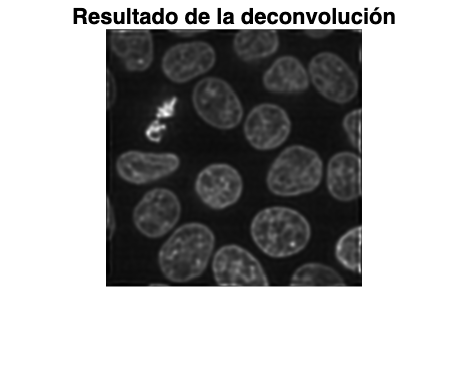

figure;
imshow(result_cell, []);  % El [] ajusta automáticamente el rango de intensidad
colormap gray;            % Escala de grises
title('Resultado de la deconvolución');

imwrite(mat2gray(result_cell), '2D_MATLAB_cell_DL2.png');  % mat2gray normaliza a [0,1]

### @ BENCHMARK

% ------------------------------
% Configuración
% ------------------------------
numIter = 10;                           % Número de ejecuciones
csvFile = 'RL_times_cell.csv';               % Nombre del CSV de salida

% Eliminar archivo previo si existe
if exist(csvFile, 'file')
    delete(csvFile);
end

% ------------------------------
% Bucle de ejecución
% ------------------------------
T_cell = zeros(numIter,1);  % Vector para guardar tiempos

for i = 1:numIter
    tic
    result_cell = DL2.RL(img_cell, psf_cell, 30, '-out');  % Ejecutar deconvolución
    T_cell(i) = toc;  % Guardar tiempo total
    
    % Guardar inmediatamente en CSV
    writematrix(T_cell(i), csvFile, 'WriteMode', 'append');
    
    fprintf('Iteración %d: %.3f s\n', i, T_cell(i));
end

Iteración 1: 0.919 s
Iteración 2: 0.835 s
Iteración 3: 0.830 s
Iteración 4: 0.835 s
Iteración 5: 0.915 s
Iteración 6: 0.856 s
Iteración 7: 0.817 s
Iteración 8: 1.028 s
Iteración 9: 0.829 s
Iteración 10: 0.815 s



disp('Todos los tiempos guardados en RL_times.csv');

Todos los tiempos guardados en RL_times.csv


disp(T_cell);

    0.9188
    0.8349
    0.8302
    0.8351
    0.9150
    0.8559
    0.8170
    1.0275
    0.8288
    0.8149



medianTime_cell = median(T_cell);
fprintf('Tiempo mediano de deconvolución: %.3f s\n', medianTime_cell);

Tiempo mediano de deconvolución: 0.835 s
